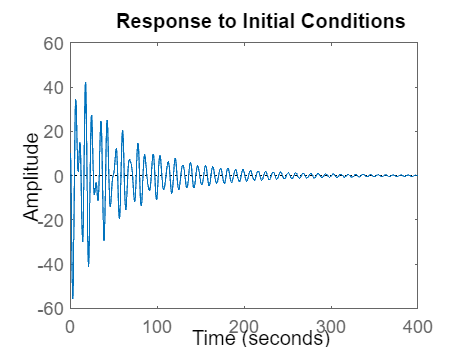

% Importing the varibales from the workspace_1G

% Taking 12 state variables(6-actual variables and 6 -estimated variable)
% The intial conditions for the Luenberger observer are:
X0 = [10,0,20,0,30,0,0,0,0,0,0,0];
% Implementation of the LQR Controller to find the K_matrix (Gain Matrix)
[K_matrix] = lqr(A,B,Q,R);
% Process noise (Notation as per the lecture notes)
U_d = diag([0.5, 0.5, 0.5, 0.5, 0.5, 0.5]);
% Measurement noise (Notation as per the lecture notes)
V_t = 1; 

% Gain matrix for Kalman Filter for C1, C2, C3
KFC = lqr(A', C1', U_d, V_t)';  

% Plot for the system_1
System_1 = ss([(A-B*K_matrix) B*K_matrix; zeros(size(A)) (A-KFC*C1)], [B;zeros(size(B))],[C1 zeros(size(C1))], D);
figure
initial(System_1,X0)

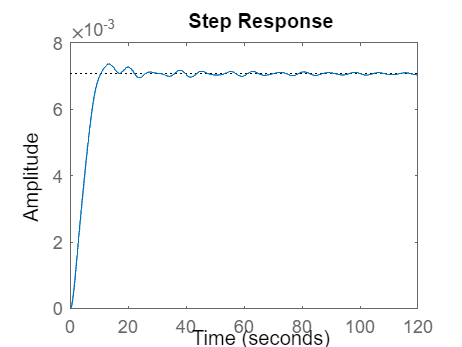

figure
step(System_1)

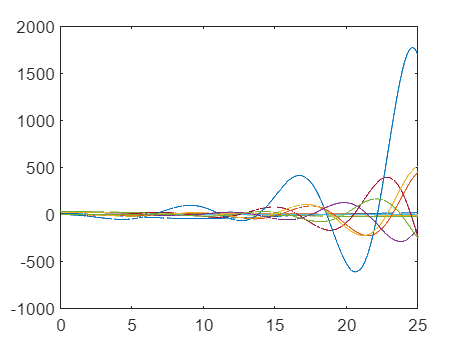

% LQG for non-linear system
X0 = [10,0,20,0,30,0,0,0,0,0,0,0];
Timespan = 0:0.01:25;
[T1,X1] = ode45(@LQG_controller,Timespan,X0);
plot(T1,X1)

function X_dot = LQG_controller(T1,X)
% Mass of the Crane
M= 1000;
% Load mass 1
m1= 100; 
% Load mass 2
m2= 100;
% Length of the cable for the 1st load
l1= 20; 
% Length of the cable for the 2nd load
l2= 10;
% Acceleration due to gravity
g= 9.81;

% A matrix
A=[0 1 0 0 0 0;
0 0 -(m1*g)/M 0 -(m2*g)/M 0;
0 0 0 1 0 0;
0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
0 0 0 0 0 1;
0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

% B matrix
B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

% We assume the values of Q and R which are a part of cost function
Q = diag([50, 100, 150, 200, 250, 300]);
R = 0.0025;

% Corresponding to 1st output vector - x(t)
C1 = [1 0 0 0 0 0]; 
% Assuming the D matrix as zero
D = 0; 

[K_matrix] = lqr(A,B,Q,R);
F = - K_matrix*X(1:6);

% Process noise (Notation as per the lecture notes)
U_d = diag([0.5, 0.5, 0.5, 0.5, 0.5, 0.5]);
% Measurement noise (Notation as per the lecture notes)
V_t=1; 
% Gain matrix for Kalman Filter for C1
KFC =lqr(A', C1', U_d, V_t)';
% Standard Deviation considering C1
SD = (A-KFC*C1)*X(7:12);
X_dot = zeros(12,1);

% X(1) = x
X_dot(1) = X(2); % X_Dot

% X(2) = x_dot
X_dot(2) = (F-(g/2)*(m1*sind(2*X(3))+m2*sind(2*X(5)))-(m1*l1*(X(4)^2)*sind(X(3)))-(m2*l2*(X(6)^2)*sind(X(5))))/(M+m1*((sind(X(3)))^2)+m2*((sind(X(5)))^2)); % X_Doubledot

% X(3) = Theta_1
X_dot(3) = X(4); % Theta_1 dot

% X(4) = Theta_1 dot
X_dot(4) = (X_dot(2)*cosd(X(3))-g*(sind(X(3))))/l1'; % Theta_1 Doubledot;

% X(5)= Theta_2
X_dot(5) = X(6); % Theta_2 Dot

% X(6)= Theta_2 dot;
X_dot(6) = (X_dot(2)*cosd(X(5))-g*(sind(X(5))))/l2; % Theta_2 Doubledot;

% X(7), X(8), X(9), X(10), X(11), X(12)
X_dot(7) = X(2)-X(10);
X_dot(8) = X_dot(2)-SD(2);
X_dot(9) = X(4)-X(11);
X_dot(10) = X_dot(4)-SD(4);
X_dot(11) = X(6)-X(12);
X_dot(12) = X_dot(6)-SD(6);
end